clc, clearvars;
function [MOVINGREG] = registerMarsImages(MOVING,FIXED)

% Feature-based techniques require license to Computer Vision Toolbox
checkLicense()

% Default spatial referencing objects
fixedRefObj = imref2d(size(FIXED));
movingRefObj = imref2d(size(MOVING));

% Detect SURF features
fixedPoints = detectSURFFeatures(FIXED,'MetricThreshold',750.000000,'NumOctaves',3,'NumScaleLevels',5);
movingPoints = detectSURFFeatures(MOVING,'MetricThreshold',750.000000,'NumOctaves',3,'NumScaleLevels',5);

% Extract features
[fixedFeatures,fixedValidPoints] = extractFeatures(FIXED,fixedPoints,'Upright',false);
[movingFeatures,movingValidPoints] = extractFeatures(MOVING,movingPoints,'Upright',false);

% Match features
indexPairs = matchFeatures(fixedFeatures,movingFeatures,'MatchThreshold',50.000000,'MaxRatio',0.500000);
fixedMatchedPoints = fixedValidPoints(indexPairs(:,1));
movingMatchedPoints = movingValidPoints(indexPairs(:,2));
MOVINGREG.FixedMatchedFeatures = fixedMatchedPoints;
MOVINGREG.MovingMatchedFeatures = movingMatchedPoints;

% Apply transformation - Results may not be identical between runs because of the randomized nature of the algorithm
tform = estimateGeometricTransform2D(movingMatchedPoints,fixedMatchedPoints,'projective');
MOVINGREG.Transformation = tform;
MOVINGREG.RegisteredImage = imwarp(MOVING, movingRefObj, tform, 'OutputView', fixedRefObj, 'SmoothEdges', true);

% Store spatial referencing object
MOVINGREG.SpatialRefObj = fixedRefObj;

end

function checkLicense()

% Check for license to Computer Vision Toolbox
CVTStatus = license('test','Video_and_Image_Blockset');
if ~CVTStatus
    error(message('images:imageRegistration:CVTRequired'));
end

end

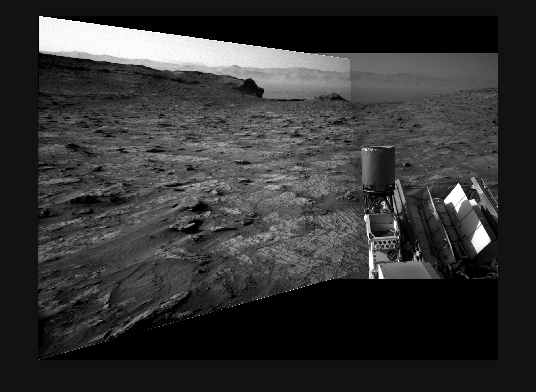

% Load images as grayscale (2D)
fixedImg = im2gray(imread("sol_03333_opgs_edr_ncam_NLB_693387385EDR_F0921230NCAM00259M_.JPG"));
leftImg = im2gray(imread("sol_03333_opgs_edr_ncam_NLB_693387301EDR_F0921230NCAM00259M_.JPG"));

% Register images
reg = registerMarsImages(leftImg, fixedImg);
movingT = reg.Transformation;
fixedT = rigidtform2d();

% Calculate panorama bounds
[nrows, ncols] = size(leftImg);
[xlimMoving, ylimMoving] = outputLimits(movingT, [1 ncols], [1 nrows]);
[nrows1, ncols1] = size(fixedImg);
[xlimFixed, ylimFixed] = outputLimits(fixedT, [1 ncols1], [1 nrows1]);

xMin = min([xlimMoving, xlimFixed]);
xMax = max([xlimMoving, xlimFixed]);
yMin = min([ylimMoving, ylimFixed]);
yMax = max([ylimMoving, ylimFixed]);

% Initialize 2D panorama
w = round(xMax - xMin);
h = round(yMax - yMin);
panorama = zeros(h, w, "uint8"); % 2D array

% Create blender for grayscale
blender = vision.AlphaBlender("Operation","Binary Mask","MaskSource","Input port");
panoramaView = imref2d([h w], [xMin xMax], [yMin yMax]);

% Warp images (will be 2D)
movingWarped = imwarp(leftImg, movingT, "OutputView", panoramaView);
fixedWarped = imwarp(fixedImg, fixedT, "OutputView", panoramaView);

% Create and warp masks
movingMask = true(nrows, ncols);
fixedMask = true(nrows1, ncols1);
movingMask = imwarp(movingMask, movingT, "OutputView", panoramaView);
fixedMask = imwarp(fixedMask, fixedT, "OutputView", panoramaView);

% Blend in 2D
panorama = blender(panorama, fixedWarped, fixedMask); % Fixed first
panorama = blender(panorama, movingWarped, movingMask); % Moving second

imshow(panorama);